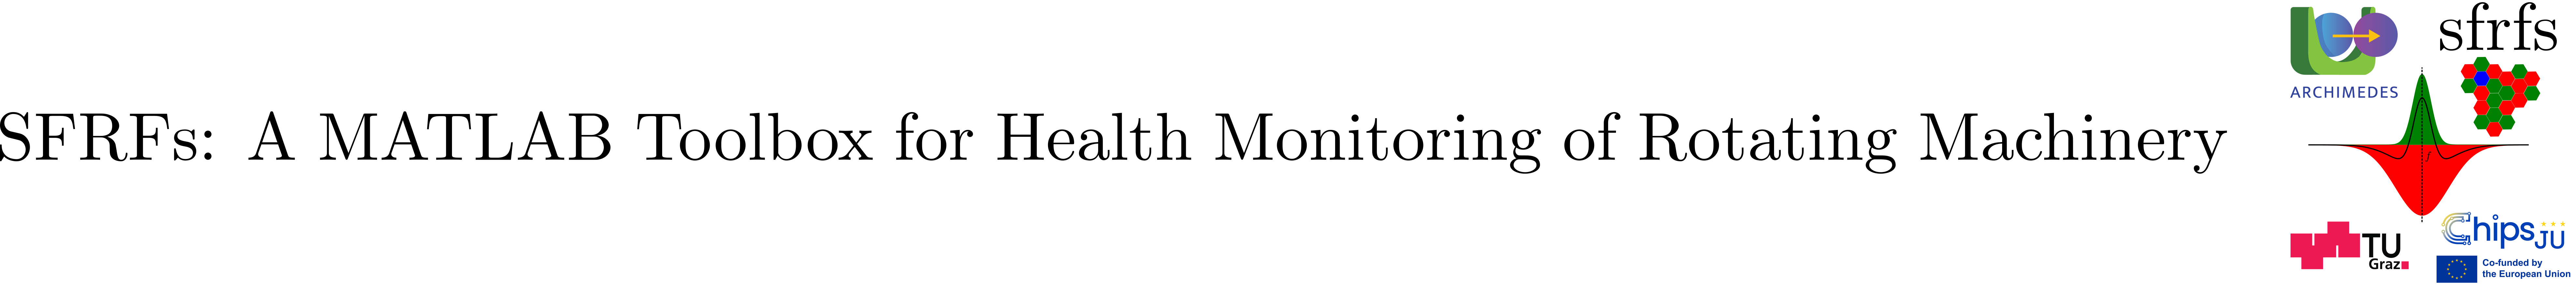

# OperatingConditionSelection

## Summary

OperatingConditionSelection defines a minimal value object for selecting a single operating condition specified by speed and load.

## Description

OperatingConditionSelection represents a single operating point anchored in the domain semantics used throughout the SFRFs framework. It stores shaft rotational speed (Hz) and load (kN) as scalar values and is used to select operating-condition-dependent records in tables keyed by operating context (for example, fault-condition tables indexed by FaultGroup, Speed, and Load). The class is intentionally minimal and enforces basic input validation to ensure physically meaningful selection values.

### Properties

## Example

% Select a concrete operating condition
sel = OperatingConditionSelection( ...
    speed = 35, ...
    load = 12);

fprintf("Selected operating condition (Speed : %.2f Hz, Load %.2f kN)",...
    sel.speed, sel.load);

Selected operating condition (Speed : 35.00 Hz, Load 12.00 kN)

## API documentation

### MATLAB help

help OperatingConditionSelection

 OperatingConditionSelection  Select an operating condition (speed, load).
 
  Usage:
    sel = OperatingConditionSelection(speed=speedHz, load=loadkN)
 
  The selection is intentionally minimal and domain-anchored:
    - speed : shaft rotational speed in Hz
    - load  : load in kN
 
  See also: OperatingConditions, FaultFrequencyBands

    Documentation for OperatingConditionSelection



## Source code

The source of the class can be found in [OperatingConditionSelection](matlab:open('../../OperatingConditionSelection.m')).

## Test

Unit testing for the class is implemented in OperatingConditionSelection.

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/TestOperatingConditionSelection');

Running TestOperatingConditionSelection
.....
Done TestOperatingConditionSelection
__________



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestOperatingConditionSelection/testValidInputs                                  | Passed
TestOperatingConditionSelection/testSpeedMustBePositive                          | Passed
TestOperatingConditionSelection/testSpeedMustBeFinite                            | Passed
TestOperatingConditionSelection/testLoadMustBeReal                               | Passed
TestOperatingConditionSelection/testLoadMustBeFinite                             | Passed



## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).